# NN MNIST digits

close all
% load data
data = load('mnist.mat');
imgs_train = data.imgs_train;
imgs_test = data.imgs_test;
labels_train = data.labels_train;
labels_test = data.labels_test;

[d1,d2,ntrain] = size(imgs_train);
Xtrain = zeros(d1,d2,1,ntrain);
for j = 1 : ntrain
    Xtrain(:,:,1,j) = imgs_train(:,:,j);
end
[d1,d2,ntest] = size(imgs_test);
Xtest = zeros(d1,d2,1,ntest);
for j = 1 : ntest
    Xtest(:,:,1,j) = imgs_test(:,:,j);
end

## Show some images

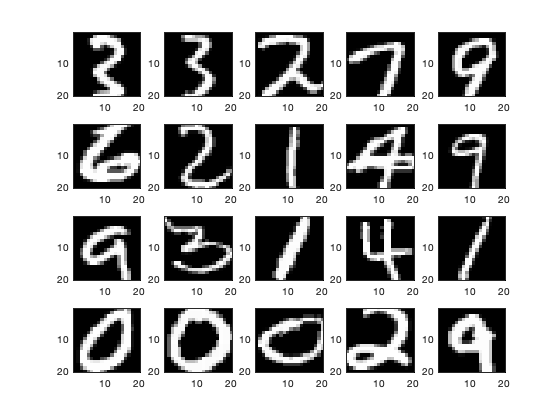

figure
colormap gray
perm = randperm(ntest,20);
for i = 1 : 20
    subplot(4,5,i);
    imagesc(imgs_test(:,:,perm(i)));
end

## Setup neural network and train it

% alexnet , Accuracy = 0.9870 , MaxEpochs = 10
%layers = [...
%    imageInputLayer([d1,d2,1])
%    convolution2dLayer(5,16,'Padding',1)
%    reluLayer
%    batchNormalizationLayer
%    maxPooling2dLayer(2,'Stride',2)
%    groupedConvolution2dLayer(3,24,2,'Padding','same')
%    reluLayer
%    batchNormalizationLayer
%    reluLayer
%    maxPooling2dLayer(2,'Stride',2)
%    fullyConnectedLayer(512)
%    reluLayer
%    dropoutLayer(0.5)
%    fullyConnectedLayer(10)
%    softmaxLayer
%    classificationLayer];

% Resnet50 , Accuracy = 0.9688
layers = [...
    imageInputLayer([d1,d2,1], 'Name', 'inputLayer')
    convolution2dLayer(5, 12, 'Name', 'conv1')
    reluLayer('Name', 'relu1')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool1')
    convolution2dLayer(5, 12, 'Name', 'conv2')
    reluLayer('Name', 'relu2')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool2')
    % Issue is at this interface
    fullyConnectedLayer(512, 'Name', 'fc1')
    reluLayer('Name', 'relu3')
    fullyConnectedLayer(512, 'Name', 'fc2')
    fullyConnectedLayer(10, 'Name', 'fc3')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'class')];

options = trainingOptions('sgdm',...
    'MaxEpochs',10,... 
    'InitialLearnRate', 1e-3,...
    'Verbose',false,...
    'Plots','training-progress');
    
net = trainNetwork(Xtrain,labels_train,layers,options);

## Classify test set

labels_test_predicted = classify(net,Xtest);
% numel returns the number of elements in the array
accuracy = sum(labels_test_predicted == labels_test)/numel(labels_test)

accuracy = 0.9688